Øvelsens formål er at studere DFT (beregnet med FFT), som den simpleste måde at analysere frekvenser af et samplet signal, samt at studere begrænsninger og fejltyper ved dette.

close all
clear
opengl hardware
format short
clc

## 1. Frekvensanalyse med DFT: fejltyper og afhjælpning

Globalt anvendes

fs = 8000;
Ts = 1/fs;

**Fejltype 1a: Aliasing i frekvens pga. undersampling i tid (fs for lille)**

Først defineres et signal med 3 frekvenskomponenter, hvorfra der tages 64 samples

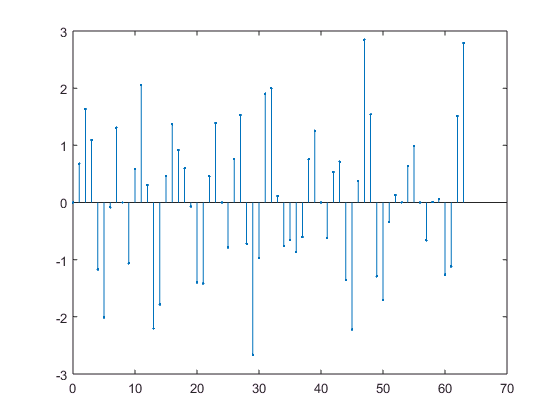

f1 = 1060;
f2 = 1560;
f3 = 6000;
N = 64;
n = 0:N-1;
x = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts) + sin(2*pi*f3*n*Ts);
stem(n,x,'.')

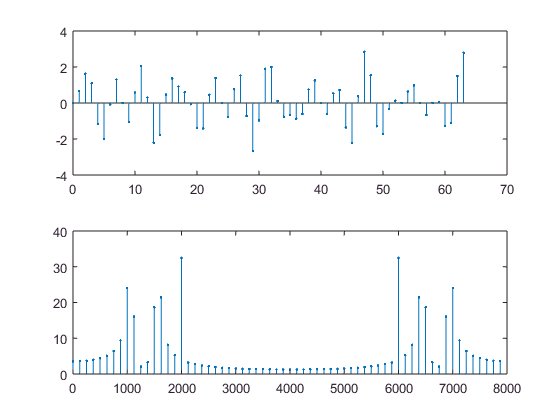

figure(2)
fftplot(x,N,fs);

Der opstår her aliasing og problemer med frekvensspektret pga. det tredje frekvenskomponent, hvis frekvens er 6000 Hz og altså noget over fs/2 = 4000. Det ser ud til, at der er en sinus ved 2000 Hz, når den i virkeligheden er ved 8000 Hz.

Der anvendes derfor kun de to første frekvenser.

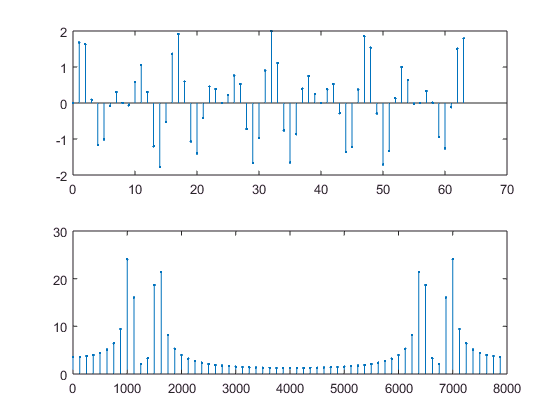

x = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
figure(3)
fftplot(x,N,fs);

**Fejltype 1b: Aliasing i tid pga. undersampling i frekvens (N for lille)**

Dette skyldes, at ved beregning af Fourier-transformationen opfattes input-signalet som den periodiske gentagelse af de N samples, der anvendes. Hvis N er for lille (ikke alle betydende samples medtages), bliver den periodiske forlængelse ikke en god repræsentation af det oprindelige signal. Dette blev illustreret i DFT_FFT_1.mlx.

**Fejltype 2: "Picketfencing" pga. for dårlig frekvensopløsning**

Frekvensopløsning for DFT er fs/N, og der kan derfor mere eller mindre "gemme" sig oplysninger/toppe i frekvensspektret, eller det kan være svært at lokalisere den præcise beliggenhed af frekvenstoppe, hvis fs/N er for stor. Dette kaldes "picketfencing".

Der er to løsninger: Højere samplingsfrekvens eller øget N-værdi. Samplingfrekvensen er oftest fast, da man udregner den i forbindelse med aliasing, og en ADC/DSP er begrænset. Derfor vil man øge N-værdien. Dette er muligt med kunstige signaler, men f.eks. et jordskælv varer kun i et bestemt antal samples. Man øger derfor samplingantallet med zero-padding, hvor der føjes nuller til enden af samplingvektoren.

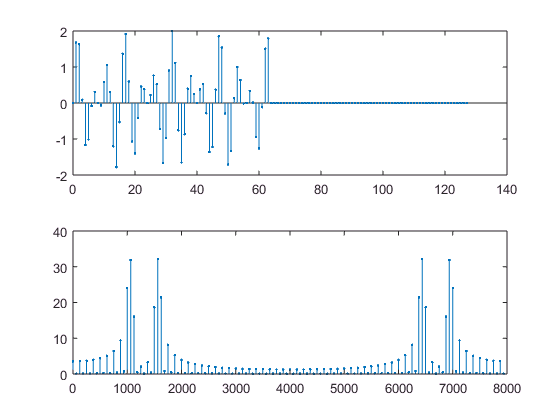

N = 128;
x128zeropad = [x zeros(1,64)]; % Der føjes 64 nuller til de oprindelige 64 data
figure(4)
fftplot(x128zeropad, N, fs);

Det bliver her nemmere at udpege, hvor frekvenstoppene er placeret.

Der prøves også zero-padding til N = 256:

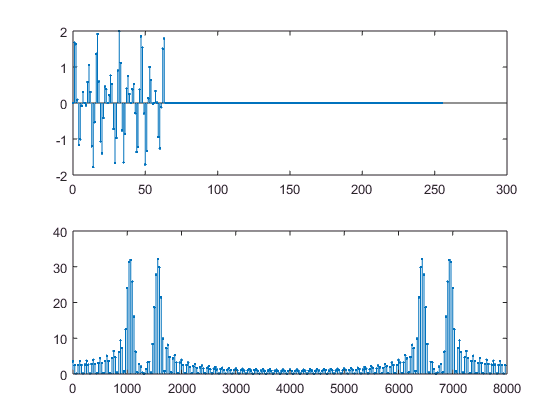

N = 256;
x128zeropad = [x zeros(1,3*64)];
figure(5)
fftplot(x128zeropad, N, fs);

Det er svært at bedømme, om yderligere nuller hjælper mere efterhånden. Et meget større antal vil ikke.

**Fejltype 3: Leakage pga. trunkering i tid**

Med trunkering menes forkortning eller afskæring af data. Der menes her, at man går fra den kontinuerte tid, hvor datasættet går til uendeligt, til en diskret tid, hvor tiden er begrænset til N samples. Når der trunkeres fra x (uendelige) samples til N, svarer det til at gange med en vinduesfunktion. Som udgangspunkt anvendes den rektangulære, da den skærer perfekt af.

Da man ganger i tidsdomænet, svarer det altså til at folde i frekvensdomænet, og frekvenserne bliver altså ændret.

Afhængigt af main-lobens bredde og side-lobens dæmpning gør dette, at frekvenser vil "lække" til nabofrekvenser, deraf navnet "leakage".

Løsningen til "leakage"-problemet er ikke entydig. En mulig løsning er at anvende andre vinduer, der også ofte anvendes ved FIR-filterdesign.

Her anvendes hamming-vinduet, som er et kompromis, der ofte anvendes. Hamming-vinduet har en cosinus-agtig form, og indeholder således ikke høje frekvenser, som en rektangel gør. Dette gør altså, at side-loberne har meget højere dæmpning end i den rektangulære. Dog er main-loben også meget større i bredden (4*fs/N frem for 2*fs/N), og da man ønsker den minimal i størrelse, skal man fordoble samplingtallet for at opnå samme main-lobe-bredde.

N = 64;
help hamming

 hamming   Hamming window.
    hamming(N) returns the N-point symmetric Hamming window in a column vector.
  
    hamming(N,SFLAG) generates the N-point Hamming window using SFLAG window
    sampling. SFLAG may be either 'symmetric' or 'periodic'. By default, a 
    symmetric window is returned. 
 
    % Example:
    %   Create a 64-point Hamming window and display the result in WVTool.
 
    L=64;
    wvtool(hamming(L))
 
    See also blackman, hann, window.

    Reference page for hamming



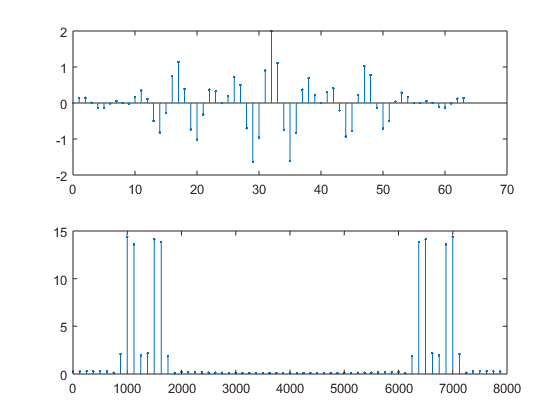

x64hamm = x.*hamming(64)';
figure(6)
fftplot(x64hamm, N, fs);

Der prøves også blackman-vinduet

N = 64;
help blackman

 blackman   Blackman window.
    blackman(N) returns the N-point symmetric Blackman window in a column
    vector.
    blackman(N,SFLAG) generates the N-point Blackman window using SFLAG
    window sampling. SFLAG may be either 'symmetric' or 'periodic'. By 
    default, a symmetric window is returned. 
 
    % Example:
    %   Create a 64-point Blackman window and display the result using 
    %   WVTool.
 
    L=64;
    wvtool(blackman(L))
 
    See also  hamming, hann, window.

    Reference page for blackman



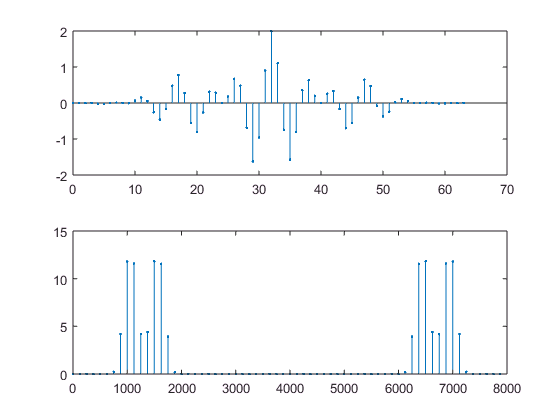

x64blackman = x.*blackman(64)';
figure(7)
fftplot(x64blackman, N, fs);

I dette tilfælde fungerer blackman-vinduet ikke så godt som hamming, idet den ønskede frekvens er dæmpet lidt, mens andre frekvenser er forstærket.

**Kombination af vinduesfunktion og zero-padding:**

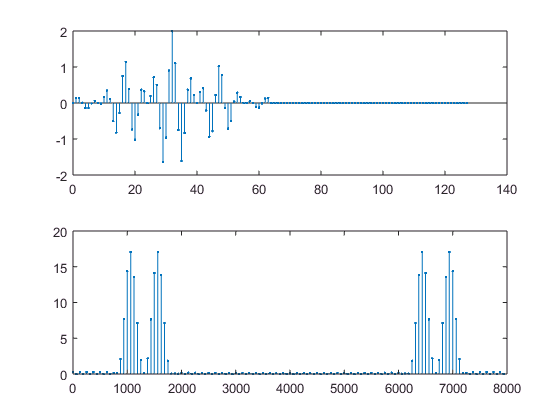

N = 128;
x128hammzero = [x.*hamming(64)' zeros(1,64)]; % De oprindelige 64 samples ganges med et hamming-vindue, og 64 nuller tilføjes
figure(8)
fftplot(x128hammzero, N, fs);

Frekvensspektret er mere centreret omkring sinusfrekvenserne.

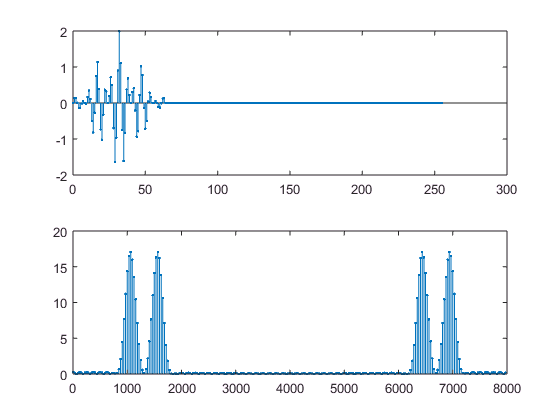

N = 256;
x256hammzero = [x.*hamming(64)' zeros(1,3*64)];
figure(9)
fftplot(x256hammzero, N, fs);

Frekvensspektret bliver ikke meget bedre, men måske lidt tydeligere.

**Den bedste løsning er altid, hvis muligt, at forøge N med ægte samples:**

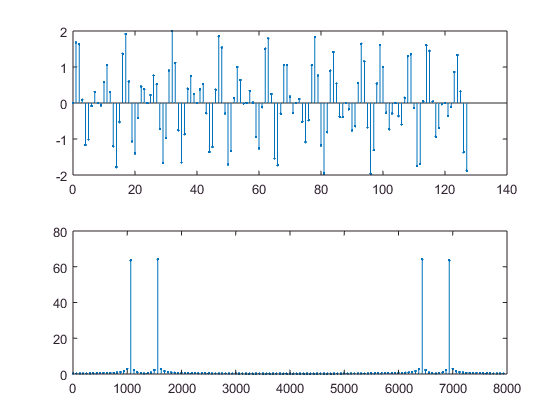

N = 128;
n = 0:N-1;
x128 = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
figure(10)
fftplot(x128, N, fs);

Frekvenserne er ekstremt tydelige på spektret.

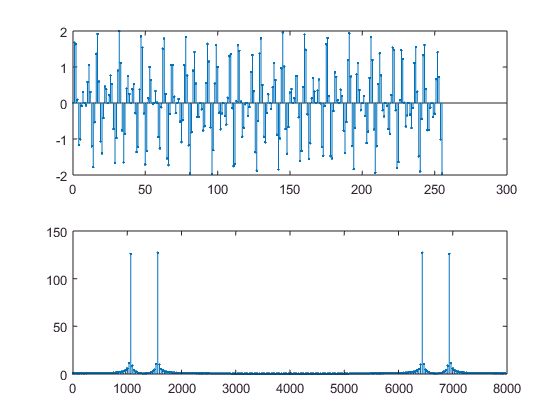

N = 256;
n = 0:N-1;
x256 = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
figure(11)
fftplot(x256, N, fs);

Flere samples bliver ikke betydeligt bedre efter dette punkt.

## 2. Frekvensopløsning

Ligesom det er vigtigt at fortolke og afhjælpe forskellige fejltyper under frekvensanalyse, er det også vigtigt at forholde sig til frekvensopløsningen.

Denne kan f.eks. defineres som den minimale frekvensforskel mellem to enkeltfrekvenser, der lige netop kan skelnes i spektret.

Ved frekvensopløsning må man skelne mellem to typer:

Den beregningsmæssige frekvensopløsning, afstanden mellem frekvenser, hvor spektret beregnes. Denne er altid fs/N.

Den fysiske frekvensopløsning, der er bestemt af den anvendte vinduesfunktion. En reel sinus lækker ved DFT over et frekvensområde svarende omtrentligt til vinduets main-lobe-bredde.

**Rektangulært vindue:**

Her er Delta-main-lobe-frekvensen (3 dB) = fs/N

ELLER

Delta-main-lobe-vinkelhastighed (3 dB) = 2pi/N

Den fysiske frekvensopløsning er altså her den samme som den beregningsmæssige.

Der defineres et signal og spektret undersøges for at se, hvornår de kan skelnes.

fs = 8000;
Ts = 1/fs;
N = 256;
fs/N

ans = 31.2500

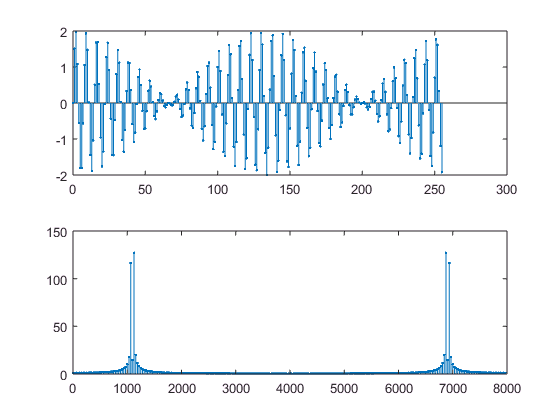

n = 0:N-1;
f1 = 1060;
f2 = 1120; % JUSTERES NED, INDTIL DE IKKE KAN SKELNES // LIGE MULIGT VED 1120
x = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
figure(12)
fftplot(x, N, fs)

**Hamming-vindue:**

Her er Delta-main-lobe-frekvensen lig 2*fs/N

ELLER

Delta-main-lobe-vinkelhastigheden = 4*pi/N

Den fysiske frekvensopløsning er altså den dobbelt af den beregningsmæssige.

2*fs/N

ans = 62.5000

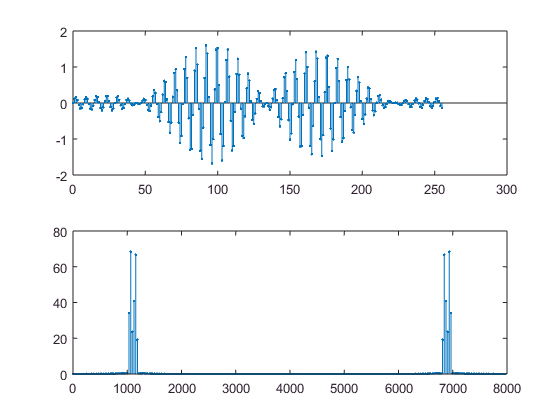

f1 = 1060;
f2 = 1150; % Omkring 1150 er det til at se dem begge, men ikke helt. Ved 1120 er de én.
x = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
xhamm = x.*hamming(N)';
figure(13)
fftplot(xhamm, N, fs);

Spektrets opførsel er forventet, idet frekvensopløsningen er højere.

**Blackman-vindue:**

Delta-main-lobe-frekvensen er lig 3*fs/N

ELLER

Delta-main-lobe-vinkelhastigheden er 6*pi/N

Den fysiske frekvensopløsning er altså 3 gange så stor som den beregningsmæssige.

3*fs/N

ans = 93.7500

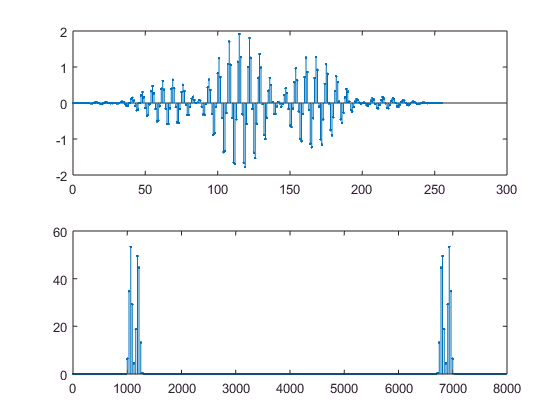

f1 = 1060;
f2 = 1200; % Det er svært at identificere to toppe før 1180-1200 Hz.
x = sin(2*pi*f1*n*Ts) + sin(2*pi*f2*n*Ts);
xblackman = x.*blackman(N)';
figure(14)
fftplot(xblackman, N, fs);

## 3. SPTOOL

MATLAB indeholder et GUI-baseret værktøj til signalanalyse og -plotting i både tids- og frekvensdomænet, bl.a. vha. DFT/FFT. GUI'en startes:

sptool